
clear
q0 =0 %%initial position

q0 = 0

v0 = 0%%initial velocity

v0 = 0

ac0 =0%% initial acceleration

ac0 = 0

q1 = 5%%final position

q1 = 5

v1 = 0%%final velocity

v1 = 0

ac1 =0%% final acceleration

ac1 = 0

t0 = 0%%initial time

t0 = 0

tf = 1%%final time

tf = 1


d = [q0,v0,ac0,q1,v1,ac1,t0,tf]

d =      0     0     0     5     0     0     0     1


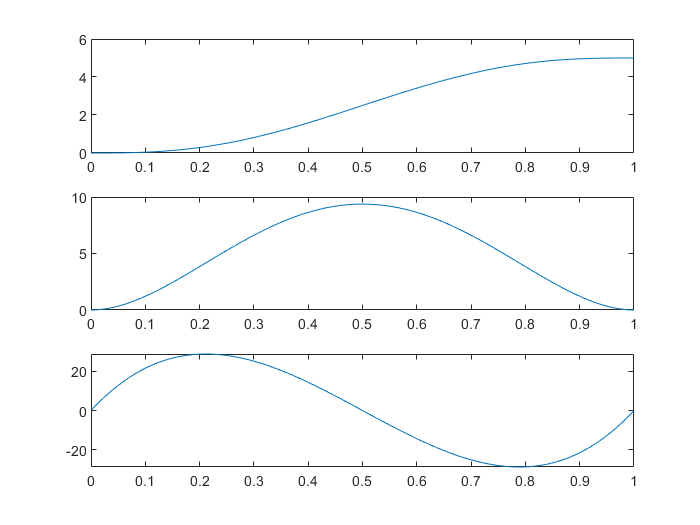

q0 = d(1); v0 = d(2); ac0 = d(3);
q1 = d(4); v1 = d(5); ac1 = d(6);
t0 = d(7); tf = d(8);
t = linspace(t0,tf,100*(tf-t0));
c = ones(size(t));
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
0 0 2 6*t0 12*t0^2 20*t0^3;
1 tf tf^2 tf^3 tf^4 tf^5;
0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
0 0 2 6*tf 12*tf^2 20*tf^3];
%%
b=[q0; v0; ac0; q1; v1; ac1];
a = M^-1*b;
%%
%% qd = position trajectory
%% vd = velocity trajectory
%% ad = acceleration trajectory
%%
qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3 +a(5).*t.^4 + a(6).*t.^5;
vd = a(2).*c +2*a(3).*t +3*a(4).*t.^2 +4*a(5).*t.^3 +5*a(6).*t.^4;
ad = 2*a(3).*c + 6*a(4).*t +12*a(5).*t.^2 +20*a(6).*t.^3;



subplot(3,1,1)
plot(t,qd)
subplot(3,1,2)
plot(t,vd)
subplot(3,1,3)
plot(t,ad)